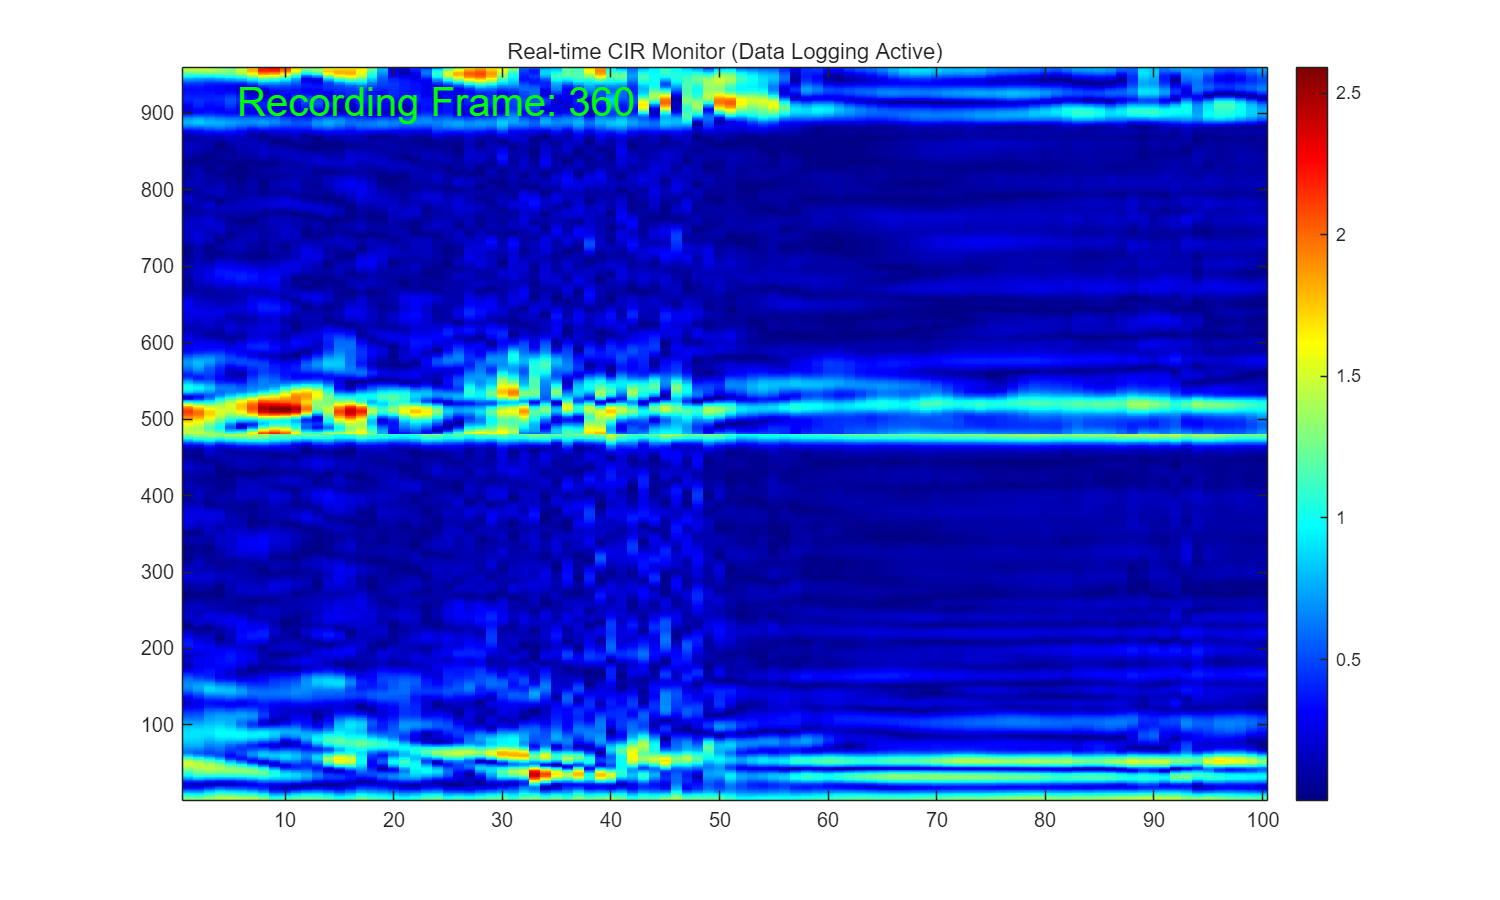

正在运行... 按 Ctrl+C 停止并自动保存数据。


校准完成。Peak位置 - Odd: 466, Even: 59


开始记录对齐后的数据...


clear; clc; close all;

% --- 信号生成 (保持不变) ---
fs = 48e3;
volume = 0.8;  
center_freq = 16e3;  
zclen = 960;  
bandwidth = 6e3;
zc_l = bandwidth/(fs/zclen);  
zc_u = [7,13]; 
wind = hamming(zc_l/2);  
for i=1:length(zc_u)
     zcseq(:,i) = zadoff_chu(zc_l/2, zc_u(i)); 
     zc_fft(:,i) = fftshift(fft(zcseq(:,i))).*wind; 
end
ofdm = zeros(zclen,2);                       
startpoint(1) = floor(center_freq/fs*zclen);  
total_point = floor((startpoint(1)-(zc_l-1)/2:startpoint(1)+(zc_l-1)/2));
odd_point = (total_point(1:2:end));
even_point = (total_point(2:2:end));
ofdm(odd_point,1) = zc_fft(:,1);
ofdm(even_point,2) = zc_fft(:,2);
ofdm(end:-1:(zclen/2+2),:) = conj(ofdm(2:zclen/2,:));
zcseq_time(:,1) = ifft(ofdm(:,1));
zcseq_time(:,2) = ifft(ofdm(:,2));

% --- 播放与采集设置 ---
play_duration = 300; 
dataout = repmat(real(zcseq_time), play_duration*fs/zclen, 1);            
dataout = dataout./max(abs(dataout)) * volume;  

samplesPerFrame = zclen;
deviceReader = audioDeviceReader('SampleRate', fs, 'NumChannels', 1, 'SamplesPerFrame', samplesPerFrame); 
player = audioplayer(dataout, fs);

% --- 显示与存储初始化 ---
figure('Position', [100, 100, 1000, 600]);
hImg = imagesc(zeros(zclen, 100)); 
colormap('jet'); colorbar; axis xy;
title('Real-time CIR Monitor (Data Logging Active)');
hText = text(0.05, 0.95, 'Initializing...', 'Color', 'white', 'FontSize', 14, 'Units', 'normalized');

% 【新增】用于存储校准阶段数据
calibration_cir_data = zeros(zclen, 20);  % 存储校准阶段的20帧原始CIR数据

% 【新增】用于存储校准后的所有采集数据
max_frames = 3000;  % 预分配空间，约10分钟
all_cir_data = zeros(zclen, max_frames); 

lock_shift_odd = []; lock_shift_even = [];  
sum_odd = zeros(zclen/2, 1); sum_even = zeros(zclen/2, 1); 
cir_buffer = zeros(zclen, 100); 

play(player); 

try
    frameCount = 0;
    validFrameCount = 0; % 记录校准后的有效帧
    updateRate = 10; 
    
    fprintf('正在运行... 按 Ctrl+C 停止并自动保存数据。\n');
    
    while true
        if ~isplaying(player), play(player); end
        
        audioFrame = deviceReader(); 
        data_fft = fft(audioFrame, [], 1);
        num_carriers = length(odd_point);
        center_idx = (zclen/2 + 1 - zc_l/2) : 2 : (zclen/2 + 1 - zc_l/2 + (num_carriers-1)*2);
        
        odd_fft_frame = zeros(size(data_fft));
        even_fft_frame = zeros(size(data_fft));
        odd_fft_frame(center_idx)  = data_fft(odd_point) .* conj(zc_fft(:,1));
        even_fft_frame(center_idx) = data_fft(even_point) .* conj(zc_fft(:,2));
        
        z_odd = (ifft(fftshift(odd_fft_frame), [], 1));
        z_even = (ifft(fftshift(even_fft_frame), [], 1));
        z_odd = z_odd(1:zclen/2);
        z_even = z_even(1:zclen/2);
        
        % 校准逻辑
        if isempty(lock_shift_odd)
            if frameCount < 20  
                sum_odd = sum_odd + z_odd;
                sum_even = sum_even + z_even;
                frameCount = frameCount + 1;
                
                % 【新增】保存校准阶段的原始CIR数据
                cir_vector_calib = [z_odd; z_even];
                calibration_cir_data(:, frameCount) = cir_vector_calib;
                
                set(hText, 'String', sprintf('Calibrating... %d/20', frameCount), 'Color', [1, 0.5, 0]);
                continue; 
            elseif frameCount == 20
                [~, p1] = max(sum_odd);
                [~, p2] = max(sum_even);
                target_pos = 1; 
                lock_shift_odd = target_pos - p1;
                lock_shift_even = target_pos - p2;
                fprintf('校准完成。Peak位置 - Odd: %d, Even: %d\n', p1, p2);
                fprintf('开始记录对齐后的数据...\n');
                set(hText, 'String', 'Recording...', 'Color', 'g', 'FontSize', 20);
            end
        end
        
        % 处理并保存数据（校准后）
        if ~isempty(lock_shift_odd)
            z_odd_shifted = circshift(z_odd, lock_shift_odd);
            z_even_shifted = circshift(z_even, lock_shift_even);
            cir_vector = [z_odd_shifted; z_even_shifted];
            
            % 存储对齐后的数据
            validFrameCount = validFrameCount + 1;
            if validFrameCount <= max_frames
                all_cir_data(:, validFrameCount) = cir_vector;
            else
                % 动态扩展
                all_cir_data = [all_cir_data, zeros(zclen, max_frames)];
                max_frames = max_frames * 2;
                all_cir_data(:, validFrameCount) = cir_vector;
            end
            
            % 更新滚动显示缓冲区
            cir_buffer(:,1:end-1) = cir_buffer(:,2:end);
            cir_buffer(:,end) = cir_vector;
            
            frameCount = frameCount + 1;
            if mod(frameCount, updateRate) == 0
                set(hImg, 'CData', abs(cir_buffer));
                set(hText, 'String', sprintf('Recording Frame: %d', validFrameCount));
                drawnow limitrate;
            end
        end
    end
    
catch ME
    if strcmp(ME.identifier, 'MATLAB:interrupt')
        fprintf('\n检测到用户停止 (Ctrl+C)。正在保存数据...\n');
    else
        fprintf('\n程序因错误停止: %s\n', ME.message);
    end
end


% --- 停止播放器和释放资源 ---
try
    stop(player);
    delete(player);
    fprintf('播放器已停止。\n');
catch
    % 忽略错误
end

try
    release(deviceReader);
    fprintf('音频输入设备已释放。\n');
catch
    % 忽略错误
end
